# DOMAIN regions ROI statistics - final

This report contains the analysis of planned comparisons for color effect, shape effect, interaction of shape x color, and the congruency effect, all in the DOMAIN regions (FFA, PPA,LOC)

The ROIs are defined as 50 best voxels within 8mm spheres centred on: 

peaks = [40 -54 -22;...

    -38 -52 -18;...

    30 -46 -10;...

    -26 -42 -14;...

    50 -62 -4 ;...

    -50 -68 -6];

 coords_voxel = [25 36 25;...

     64 37 27;...

     30 40 31;...

     58 42 29;...

     20 32 34;...

     70 29 33];

for the following areas:

names = {'FFA_right'; 'FFA_left'; 'PPA_right'; 'PPA_left'; 'LOC_right'; 'LOC_left'};

## Load data

clear
clc
close all


cd /Users/k.siudakrzywicka/Desktop/RDS_fMRI/Controls/colorRegions_rois/from_secondLevel_peaks/domain-regions/corrected/best_50_vox/

megaTable=readtable('megaTable_bin_best_50vox_spmT_0001_confiles.csv'); %note that conefiles of a single beta vs 0 equals the valie of beta, so it doesn't matter if you take beta or con files

% ROI = cell(1,40);
% k = regexp(megaTable.Properties.VariableNames, '_', 'once');
% idx = [k{:}]';
% 
% for n = 1:length(idx)
%     ROI{n} = megaTable.Properties.VariableNames{n}(1:idx(n)-1);
% end

megaTable.subject = [1:20]';
megaTable_long_form_s = stack(megaTable, megaTable.Properties.VariableNames(1:end-1), 'IndexVariableName','Conditions',...
    'NewDataVariableName','Response');

cond_parts = cellfun(@(x) strsplit(x, '_'), string(megaTable_long_form_s.Conditions), 'UniformOutput', 0);

megaTable_long_form_s.ROI = cellfun(@(x) x(1),  cond_parts);
megaTable_long_form_s.Side = cellfun(@(x) x(2),  cond_parts);
megaTable_long_form_s.Conditions =  cellfun(@(x) strjoin(x(3:end),'-'), cond_parts, 'UniformOutput', 0);
megaTable_long_form_s = megaTable_long_form_s(:, [5, 4, 2, 1, 3]);
megaTable_for_contrasts = unstack(megaTable_long_form_s, 'Response', 'Conditions');

## Define contrasts and check for orthogonality

It is important than all contrasts tested in the ROI analysis are orthogonal with the contrasts used to create the ROIs (all color vs grey-scale). For the orthogonality between contrasts for ROI analysis, it is not crucial bc a seperate model is created for each contrast.


% CONTRASTS

%all color vs greyscale

c0 = [-0.5 0.33 0.33 -0.5 0.33];

%object vs abstract color
c1 = [1 -1 0.5 -1 0.5];
%object_goodcol vs. abstract and incongruent color
c1_2 = [1 -1 1 -0.5 -0.5];
%object vs abstract shape (shape effect)
c2 = [-0.5 -0.5 0.33 0.33 0.33];
%congruency effect (good vs bad)
c3 = [0 0 1 0 -1];
%congruency effect (bad vs good)
c4 = [0 0 -1 0 1];

% check contrast orthogonality with c0 (all sums should = 0)


%Psin = sum(cn * condition mean per subj)
megaTable_for_contrasts.psi0 = sum(c0.*megaTable_for_contrasts{:, 4:8}, 2);
megaTable_for_contrasts.psi1 = sum(c1.*megaTable_for_contrasts{:, 4:8}, 2);
megaTable_for_contrasts.psi2 = sum(c2.*megaTable_for_contrasts{:, 4:8}, 2);
megaTable_for_contrasts.psi3 = sum(c3.*megaTable_for_contrasts{:, 4:8}, 2);
megaTable_for_contrasts.psi4 = sum(c4.*megaTable_for_contrasts{:, 4:8}, 2);
megaTable_for_contrasts.psi1_2 = sum(c1_2.*megaTable_for_contrasts{:, 4:8}, 2);

contrasts_within_factors = unique(megaTable_for_contrasts(:, 1:2), 'stable');
contrasts_within_factors.Side_by_ROI = categorical(contrasts_within_factors.Side).*categorical (contrasts_within_factors.ROI);

Let's plot the activity in each of the condition that interests us by Side (separate plots) and ROI (x axis)

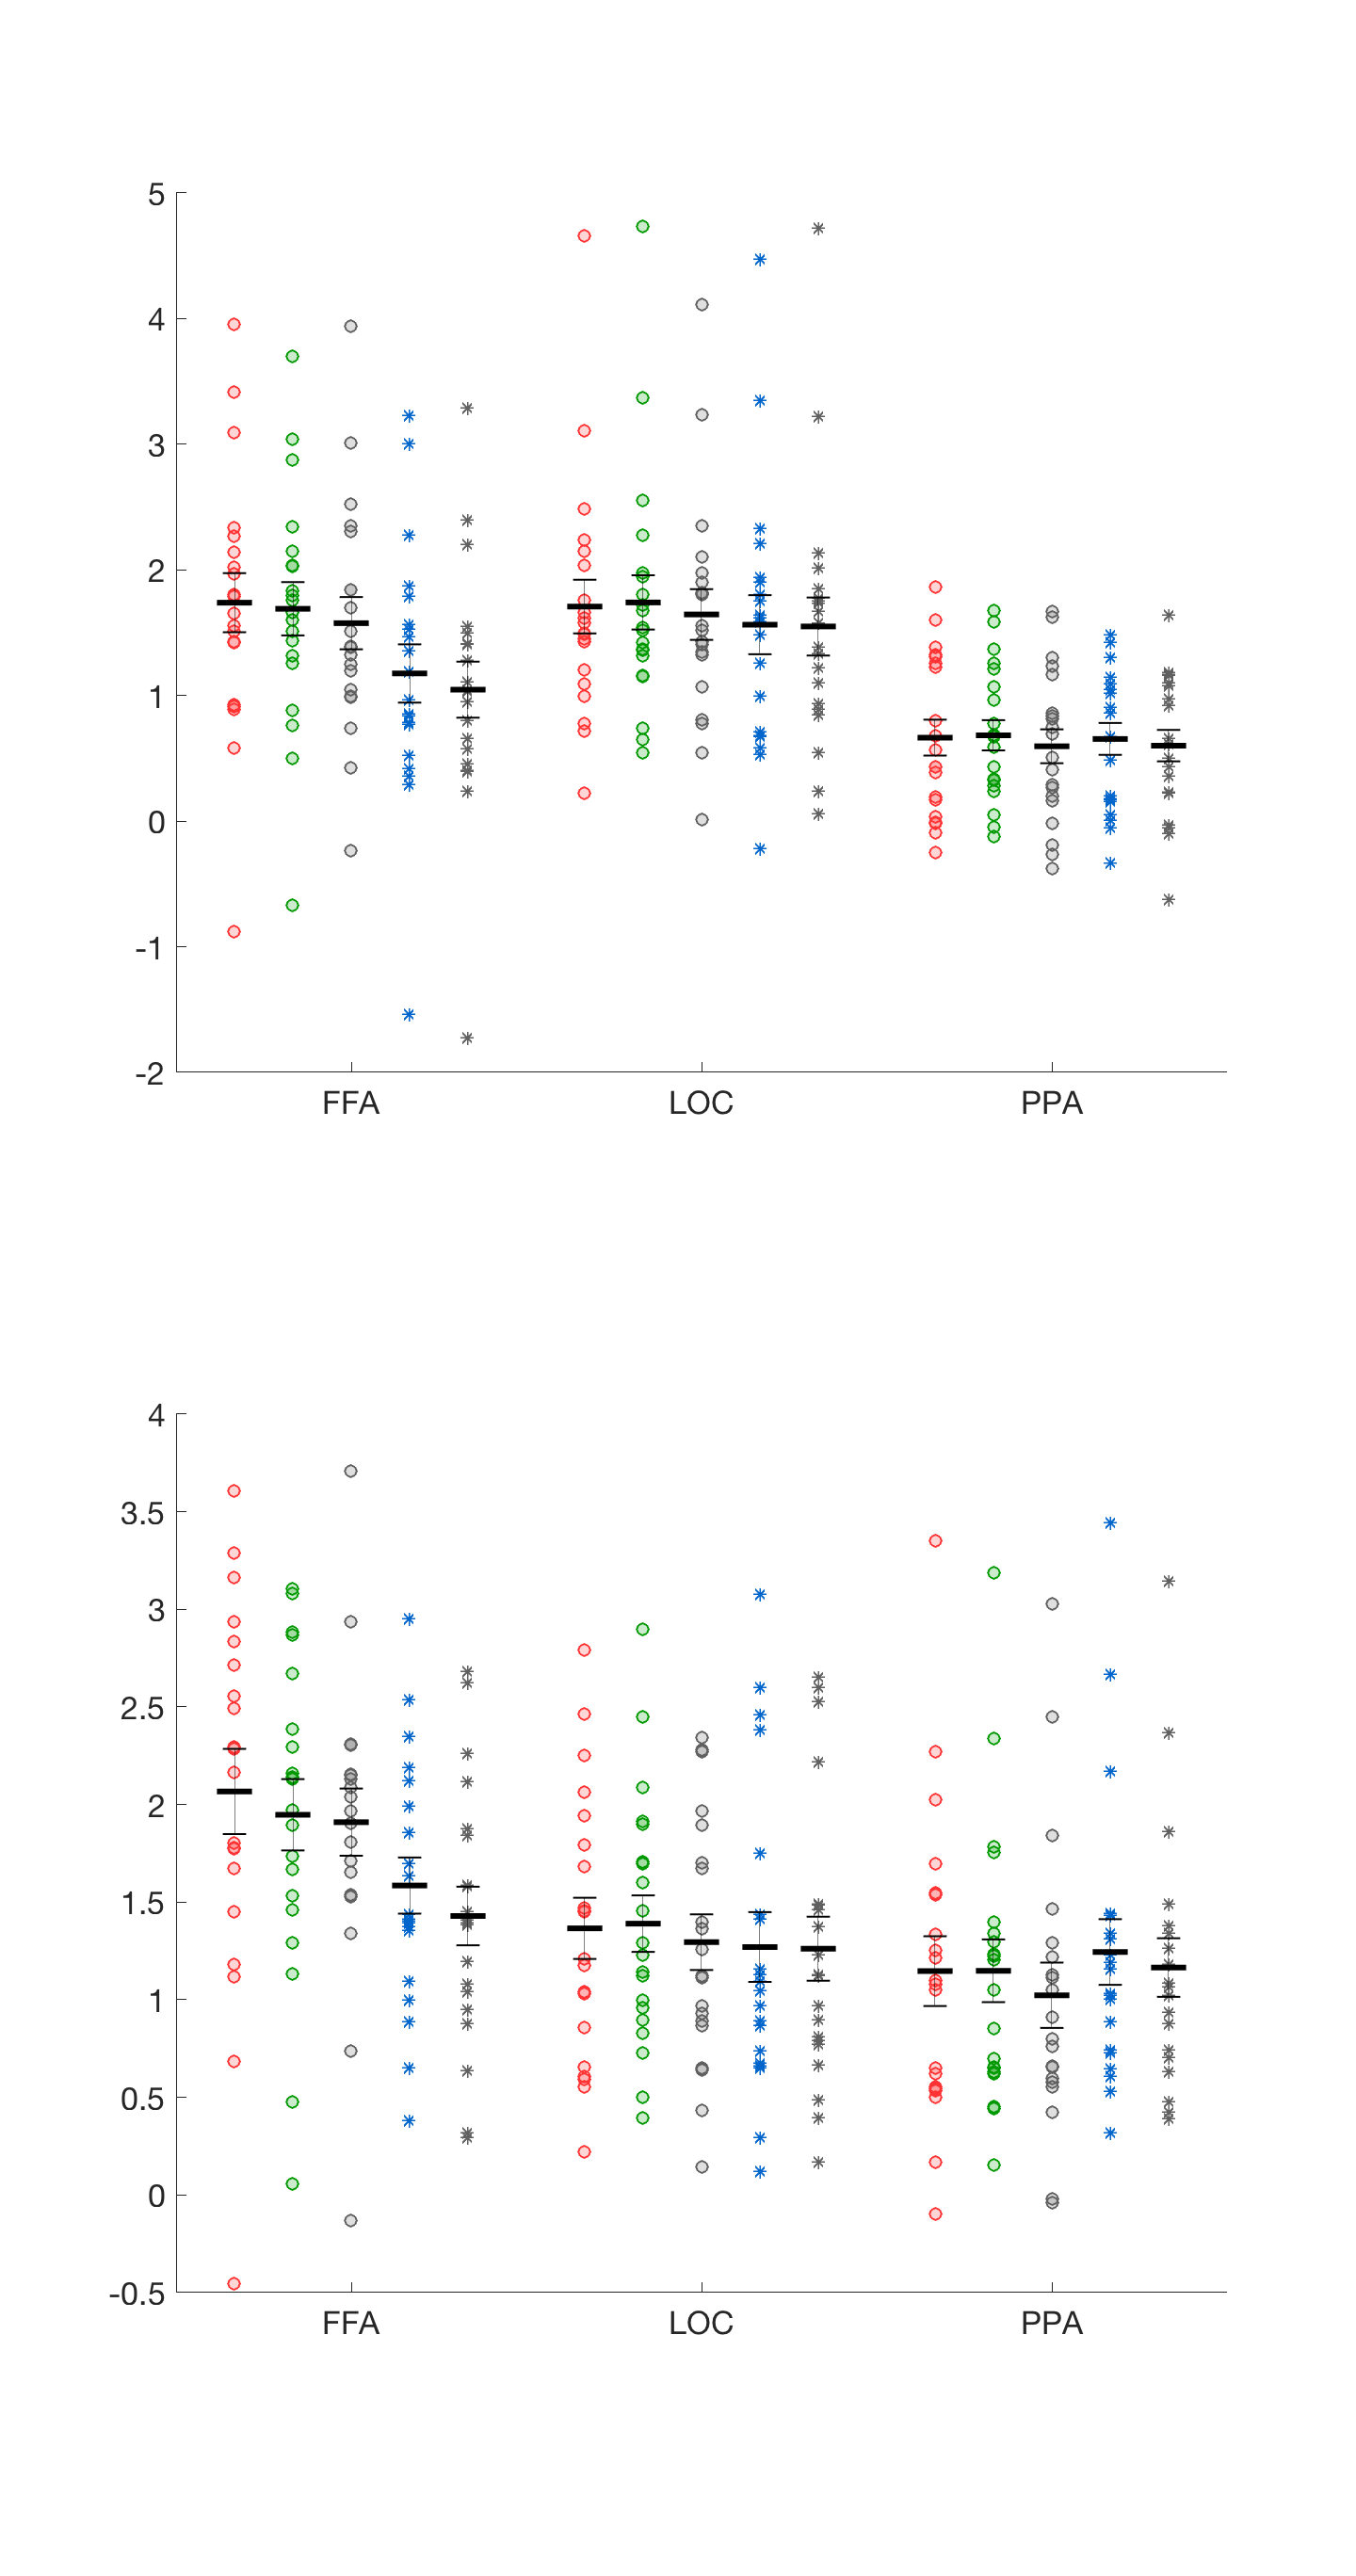

data_to_plot = megaTable_for_contrasts(:, [1:3,8,6,7,5,4]);

[g, side, rois] = findgroups(data_to_plot.Side, data_to_plot.ROI);

colors = [255 51 51; 0 153 0; 96 96 96;0 102 204; 96 96 96]./255;
markers = {'o', 'o', 'o', '*','*'};


figure ('units', 'inches')

subplot(2, 1 ,1)
xlim([0 9])
xticks([1.5 4.5 7.5])
xticklabels({'FFA', 'LOC', 'PPA'})

x = 0:0.5:9;
x = x(mod(x,3)~=0);

for roi = 1:3
     for condition = 1:5
            x_value = (roi-1)*5+condition;
            hold on
            y = data_to_plot{g==roi, condition+3};
            meany = mean(y);
                scatter(x(x_value).* ones(20,1), y,...
                    40,  markers{condition},'MarkerEdgeColor',colors(condition, :),...
                    'MarkerFaceColor',colors(condition, :))
                    alpha(.2)
                hold on
                plot([x(x_value)-0.15 x(x_value)+0.15],[meany meany],...
                    'Color', 'k', 'LineWidth', 3)
                hold on
                    sem=std(y)/sqrt(20);
                    CI=sem*1.96;
                    plot([x(x_value)-0.1 x(x_value)+0.1],[meany+sem meany+sem],'Color','k','LineWidth',1)
                    plot([x(x_value)-0.1 x(x_value)+0.1],[meany-sem meany-sem],'Color','k','LineWidth',1)
                    plot([x(x_value) x(x_value)],[meany-sem meany+sem],'Color','k')
            hold off
       
    end
end

subplot(2, 1,2)
xlim([0 9])
xticks([1.5 4.5 7.5])
xticklabels({'FFA', 'LOC', 'PPA'})

x = 0:0.5:9;
x = x(mod(x,3)~=0);

for roi = 1:3
     for condition = 1:5
        x_value = (roi-1)*5+condition;
            hold on
            y = data_to_plot{g==roi+3, condition+3};
            meany = mean(y);
                scatter(x(x_value).* ones(20,1), y,...
                     40, markers{condition},'MarkerEdgeColor',colors(condition, :),...
                    'MarkerFaceColor',colors(condition, :))
                    alpha(.2)
                hold on
                plot([x(x_value)-0.15 x(x_value)+0.15],[meany meany],...
                    'Color', 'k', 'LineWidth', 3)
                hold on
                    sem=std(y)/sqrt(20);
                    CI=sem*1.96;
                    plot([x(x_value)-0.1 x(x_value)+0.1],[meany+sem meany+sem],'Color','k','LineWidth',1)
                    plot([x(x_value)-0.1 x(x_value)+0.1],[meany-sem meany-sem],'Color','k','LineWidth',1)
                    plot([x(x_value) x(x_value)],[meany-sem meany+sem],'Color','k')
            hold off
       
    end
end

set(gcf,'Units','inches','Position',[0 0 10 19])

## The main effect of color

tmp = unstack (megaTable_for_contrasts(:, [1 2 3 9]), 'psi0', 'ROI');
psi0 = unstack (tmp, tmp.Properties.VariableNames(3:end), 'Side');
psi0.Properties.VariableNames(2:end) = strcat('psi0_', psi0.Properties.VariableNames(2:end));

%fir the model with firrm
Color_rm = fitrm(psi0,'psi0_FFA_left-psi0_PPA_right~1',...
    'WithinDesign',contrasts_within_factors);

% run ANOVA
Color_anova = ranova(Color_rm, 'WithinModel','Side*ROI' )

Color_anova = 8×8 table
                              SumSq      DF     MeanSq         F         pValue      pValueGG     pValueHF     pValueLB 
                            _________    __    _________    ________    _________    _________    _________    _________

    (Intercept)                 1.324     1        1.324      12.912    0.0019378    0.0019378    0.0019378    0.0019378
    Error                      1.9483    19      0.10254                                                                
    (Intercept):Side        0.0020081     1    0.0020081    0.085409      0.77326      0.77326      0.77326      0.77326
    Error(Side)               

The model shows a significant main effect of ROI. The main effect of side and the interaction SidexROI is not significant. 

Let's look at the effects in each ROI using marginal means:

Color_margMeans_x_ROI = margmean(Color_rm, 'ROI')

Color_margMeans_x_ROI = 3×5 table
     ROI       Mean       StdErr       Lower        Upper 
    _____    ________    ________    __________    _______

    'FFA'     0.19332    0.049132      0.090485    0.29615
    'LOC'    0.053569    0.029666    -0.0085219    0.11566
    'PPA'    0.068229    0.028788      0.007975    0.12848


There is a significant effect in FFA and PPA. No effect in LOC.

post_hoc_Color_anova_ROI = multcompare(Color_rm,'ROI');
post_hoc_Color_anova_ROI(post_hoc_Color_anova_ROI.pValue<0.07, :)

ans = 4×7 table
    ROI_1    ROI_2    Difference     StdErr      pValue        Lower        Upper   
    _____    _____    __________    ________    _________    _________    __________

    'FFA'    'LOC'     0.13975      0.036972    0.0034592     0.045824       0.23368
    'FFA'    'PPA'     0.12509      0.047545     0.041628    0.0043045       0.24587
    'LOC'    'FFA'    -0.13975      0.036972    0.0034592     -0.23368     -0.045824
    'PPA'    'FFA'    -0.12509      0.047545     0.041628     -0.24587    -0.0043045


The strongest color effect is in the FFA. There is no significant difference between the effects in the PPA and LOC. 

## The main effect of shape

%prepare data set for analysis
tmp = unstack (megaTable_for_contrasts(:, [1 2 3 11]), 'psi2', 'ROI');
psi2 = unstack (tmp, tmp.Properties.VariableNames(3:end), 'Side');
psi2.Properties.VariableNames(2:end) = strcat('psi2_', psi2.Properties.VariableNames(2:end));
% fir fm model
shape_rm = fitrm(psi2,'psi2_FFA_left-psi2_PPA_right~1',...
    'WithinDesign',contrasts_within_factors);
%ANOVA
shape_anova = ranova(shape_rm, 'WithinModel','Side*ROI' )

shape_anova = 8×8 table
                             SumSq      DF     MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                            ________    __    ________    _______    __________    __________    __________    _________

    (Intercept)               3.9494     1      3.9494     12.439     0.0022531     0.0022531     0.0022531    0.0022531
    Error                     6.0323    19     0.31749                                                                  
    (Intercept):Side         0.24294     1     0.24294     2.7846       0.11157       0.11157       0.11157      0.11157
    Error(Side)               

The shape model showed sigificant main effect of ROI.

Shape_margMeans_x_ROI = margmean(shape_rm, 'ROI')

Shape_margMeans_x_ROI = 3×5 table
     ROI       Mean        StdErr       Lower       Upper  
    _____    _________    ________    _________    ________

    'FFA'       0.4944    0.090984      0.30397     0.68483
    'LOC'     0.097715    0.044295    0.0050045     0.19043
    'PPA'    -0.047866    0.051696     -0.15607    0.060334


The strongest sgape effect is in the FFA, and there is also some effect in the LOC. 

No effect in PPA

post_hoc_shape_anova_ROI = multcompare(shape_rm,'ROI');
post_hoc_shape_anova_ROI(post_hoc_shape_anova_ROI.pValue<0.07, :)

ans = 6×7 table
    ROI_1    ROI_2    Difference     StdErr       pValue       Lower       Upper  
    _____    _____    __________    ________    __________    ________    ________

    'FFA'    'LOC'     0.39668      0.086214    0.00054636     0.17766     0.61571
    'FFA'    'PPA'     0.54226      0.068656    5.8876e-07     0.36785     0.71668
    'LOC'    'FFA'    -0.39668      0.086214    0.00054636    -0.61571    -0.17766
    'LOC'    'PPA'     0.14558       0.05272      0.031821     0.01165     0.27951
    'PPA'    'FFA'    -0.54226      0.068656    5.8876e-07    -0.71668    -0.36785
    'PPA'    'LOC'    -0.14558       0.05272      0.031821    -0.27951    -0.01165


The object shape effect is strongest in FFA, then LOC, then PPA (all differences significant). 

The pb is that, as we have an effect of shape and color in the FFA, and we see from the graph and the stats that shape effect is very strong, could it be that in the FFA the variance for color effect could be accounted by the variance of the shape effect? To verify that lets run a model with color and shape effect together.

## A model of shape and color contrasts together

%contrasts orthogonality
sum(c0.*c2)

ans = 0.1378

not good, but not terrible

data = innerjoin(psi0, psi2, 'LeftKeys',1,'RightKeys',1);
condition = table(reshape(repmat(categorical({'color', 'object'}), 6,1), [], 1), 'VariableNames', {'Condition'});
within_factor = [condition, repmat(contrasts_within_factors, 2, 1)] ;
within_factor.Condition_by_ROI = within_factor.Condition.*within_factor.ROI;


color_shape_rm = fitrm(data,'psi0_FFA_left-psi2_PPA_right~1',...
    'WithinDesign',within_factor);
%ANOVA
color_shape_anova = ranova(color_shape_rm, 'WithinModel','Condition*Side*ROI' )

color_shape_anova = 16×8 table
                                       SumSq      DF     MeanSq         F          pValue       pValueGG      pValueHF      pValueLB 
                                      ________    __    _________    ________    __________    __________    __________    __________

    (Intercept)                         4.9234     1       4.9234      18.183    0.00041926    0.00041926    0.00041926    0.00041926
    Error                               5.1446    19      0.27077                                                                    
    (Intercept):Condition                 0.35     1         0.35      2.3449       0.14217       0.14217    


color_shape_margMeans_x_Condition_by_ROI = margmean(color_shape_rm, 'Condition_by_ROI')

color_shape_margMeans_x_Condition_by_ROI = 6×5 table
    Condition_by_ROI      Mean        StdErr       Lower        Upper  
    ________________    _________    ________    __________    ________

    color FFA             0.19332    0.049132      0.090485     0.29615
    color LOC            0.053569    0.029666    -0.0085219     0.11566
    color PPA            0.068229    0.028788      0.007975     0.12848
    object FFA             0.4944    0.090984       0.30397     0.68483
    object LOC           0.097715    0.044295     0.0050045     0.19043
    object PPA          -0.047866    0.051696      -0.15607    0.060334


post_hoc_color_shape_anova_Condition_by_ROI = multcompare(color_shape_rm, 'Condition_by_ROI');
post_hoc_color_shape_anova_Condition_by_ROI(post_hoc_color_shape_anova_Condition_by_ROI.pValue<0.07 &...
    post_hoc_color_shape_anova_Condition_by_ROI.Difference>0, :)

ans = 7×7 table
    Condition_by_ROI_1    Condition_by_ROI_2    Difference     StdErr       pValue        Lower       Upper 
    __________________    __________________    __________    ________    __________    _________    _______

    color FFA             color LOC             0.13975       0.036972      0.013717      0.02293    0.25657
    color FFA             object PPA            0.24118       0.073305      0.038363    0.0095649     0.4728
    object FFA            color FFA             0.30108       0.084243      0.021254     0.034899    0.56726
    object FFA            color LOC             0.44083       0.091539     0.0014434       0.1516    0.73006
    object FFA            color PPA             0.42617       0.085132     0.0009544      0

## The shape x color interaction (any object color - good or bad - vs mondrian color)

This contrast weights correspond to the situation where signals for (object good color+object bad color) - object GS are greated than signals for mondrian color vs mondrian GS. This is why the positive values of thi contrasts should be expected in object color region rather than abstract color region. 

%prepare data set for analysis
tmp = unstack (megaTable_for_contrasts(:, [1 2 3 10]), 'psi1', 'ROI');
psi1 = unstack (tmp, tmp.Properties.VariableNames(3:end), 'Side');
psi1.Properties.VariableNames(2:end) = strcat('psi1_', psi1.Properties.VariableNames(2:end));

%fir the model with firrm
objectColor_rm = fitrm(psi1,'psi1_FFA_left-psi1_PPA_right~1',...
    'WithinDesign',contrasts_within_factors);

% run ANOVA
objectColor_anova = ranova(objectColor_rm, 'WithinModel','Side*ROI' )

objectColor_anova = 8×8 table
                              SumSq      DF     MeanSq         F        pValue     pValueGG    pValueHF    pValueLB
                            _________    __    _________    ________    _______    ________    ________    ________

    (Intercept)              0.084616     1     0.084616      0.1842    0.67261    0.67261     0.67261     0.67261 
    Error                      8.7278    19      0.45936                                                           
    (Intercept):Side        0.0052528     1    0.0052528    0.092634    0.76416    0.76416     0.76416     0.76416 
    Error(Side)                1.0774    19     0

## The shape x color interaction (good object color vs bad color and mondrian color)

This contrast weights correspond to the situation where signals for (object good color+object bad color) - object GS are greated than signals for mondrian color vs mondrian GS. This is why the positive values of thi contrasts should be expected in object color region rather than abstract color region. 

%prepare data set for analysis
tmp = unstack (megaTable_for_contrasts(:, [1 2 3 14]), 'psi1_2', 'ROI');
psi1_2 = unstack (tmp, tmp.Properties.VariableNames(3:end), 'Side');
psi1_2.Properties.VariableNames(2:end) = strcat('psi1_2_', psi1_2.Properties.VariableNames(2:end));

%fir the model with firrm
objectColor2_rm = fitrm(psi1_2,'psi1_2_FFA_left-psi1_2_PPA_right~1',...
    'WithinDesign',contrasts_within_factors);

% run ANOVA
objectColor2_anova = ranova(objectColor2_rm, 'WithinModel','Side*ROI' )
objectColor2_margMeans_x_ROI = margmean(objectColor2_rm, 'ROI')
post_hoc_objectColor2_anova_ROI = multcompare(objectColor2_rm,'ROI')

## Congruency effect

Last but not least, let's see if any of our ROIs differentiate between congruent or incongruent colors. Let's strat with regions that show preference towards congruent colors.

%prepare dataset
tmp = unstack (megaTable_for_contrasts(:, [1 2 3 12]), 'psi3', 'ROI');

objectColor2_anova = 8×8 table
                             SumSq      DF     MeanSq        F         pValue      pValueGG      pValueHF     pValueLB 
                            ________    __    ________    _______    __________    _________    __________    _________

    (Intercept)                0.144     1       0.144    0.30149       0.58935      0.58935       0.58935      0.58935
    Error                     9.0752    19     0.47764                                                                 
    (Intercept):Side        0.045505     1    0.045505    0.90679       0.35293      0.35293       0.35293      0.35293
    Error(Side)             

psi3 = unstack (tmp, tmp.Properties.VariableNames(3:end), 'Side');

objectColor2_margMeans_x_ROI = 3×5 table
     ROI       Mean        StdErr       Lower       Upper  
    _____    _________    ________    _________    ________

    'FFA'     -0.14646    0.078374      -0.3105    0.017582
    'LOC'     0.050879    0.068136    -0.091733     0.19349
    'PPA'    -0.008346     0.05922      -0.1323      0.1156


psi3.Properties.VariableNames(2:end) = strcat('psi3_', psi3.Properties.VariableNames(2:end));

post_hoc_objectColor2_anova_ROI = 6×7 table
    ROI_1    ROI_2    Difference     StdErr       pValue        Lower        Upper  
    _____    _____    __________    ________    __________    _________    _________

    'FFA'    'LOC'     -0.19734     0.040971    0.00033775     -0.30142    -0.093249
    'FFA'    'PPA'     -0.13811     0.050285      0.032818     -0.26586    -0.010365
    'LOC'    'FFA'      0.19734     0.040971    0.00033775     0.093249      0.30142
    'LOC'    'PPA'     0.059225     0.053347       0.51964    -0.076301      0.19475
    'PPA'    'FFA'      0.13811     0.050285      0.032818     0.010365      0.26586
    'PPA'    'LOC'    -0.059225     0.053347       0.51964     -0.19475     0.076301



%fit rm
congruency_rm = fitrm(psi3,'psi3_FFA_left-psi3_PPA_right~1',...
    'WithinDesign',contrasts_within_factors);

%run ANOVA
congruency_anova = ranova(congruency_rm, 'WithinModel','Side*ROI' )

There is a main effect of ROI. 

Let's look at the marginal means of the interaction

Conruency_margMeans_x_ROI = margmean(congruency_rm, 'ROI')

There is a significant preference towards congruent color in the letf early ocsempital cortex. The left anterior fusiform seems to respond more strongly to the incongruent color (negative mean).

Let's se, with post-hoc tests, if there are any cross-hemispheric differences between ROIs.

post_hoc_congruency_anova_ROI = multcompare(congruency_rm,'ROI');
post_hoc_congruency_anova_ROI(post_hoc_congruency_anova_ROI.pValue<0.07, :)

congruency_anova = 8×8 table
                             SumSq      DF     MeanSq        F        pValue     pValueGG     pValueHF    pValueLB
                            ________    __    ________    _______    ________    _________    ________    ________

    (Intercept)             0.026571     1    0.026571    0.16301     0.69091      0.69091     0.69091    0.69091 
    Error                     3.0971    19       0.163                                                            
    (Intercept):Side        0.031439     1    0.031439     1.0321     0.32243      0.32243     0.32243    0.32243 
    Error(Side)              0.57876    19    0.030461 

Conruency_margMeans_x_ROI = 3×5 table
     ROI       Mean        StdErr       Lower       Upper  
    _____    _________    ________    _________    ________

    'FFA'    -0.084012    0.050475     -0.18966    0.021633
    'LOC'     0.029041     0.03649    -0.047332     0.10541
    'PPA'      0.01033    0.038616    -0.070494    0.091154


ans = 4×7 table
    ROI_1    ROI_2    Difference     StdErr      pValue        Lower         Upper  
    _____    _____    __________    ________    _________    __________    _________

    'FFA'    'LOC'     -0.11305     0.032775    0.0072239      -0.19632     -0.02979
    'FFA'    'PPA'    -0.094342      0.03968      0.06901      -0.19515    0.0064618
    'LOC'    'FFA'      0.11305     0.032775    0.0072239       0.02979      0.19632
    'PPA'    'FFA'     0.094342      0.03968      0.06901    -0.0064618      0.19515
